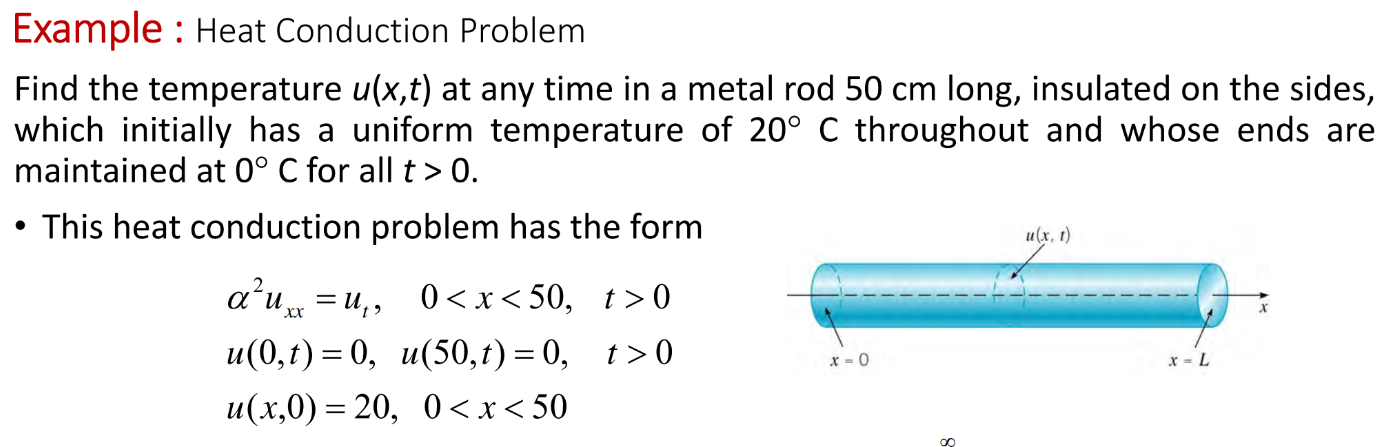

**Separation part**

clear;clf;
syms x t u(x,t) L D
assume([L D],"positive")
HeatEq = diff(u,t) == D*diff(u,x,2)

$$HeatEq(x, t) = \frac{\partial }{\partial t}u\left(x,t\right)=\text{D}\,\frac{\partial^{2}}{\partial x^{2}}u\left(x,t\right)$$

BC0 = u(0,t) == 0; BCL = u(L,t) == 0;
syms T(t) X(x)
SepVar  = subs(HeatEq,u(x,t),X(x)*T(t));
BCx0 = subs(BC0,u(0,t),X(0))

$$BCx0 = X\left(0\right)=0$$

BCxL = subs(BCL,u(L,t),X(L))

$$BCxL = X\left(L\right)=0$$

sep

SepVar = SepVar/(D*X(x)*T(t));
var = children(SepVar);
syms lambda
assume(lambda,"positive")
eqT = var(1) == -lambda^2

$$eqT = \frac{\frac{\partial }{\partial t}T\left(t\right)}{\text{D}\,T\left(t\right)}=-\lambda^{2}$$

eqX = var(2) == -lambda^2

$$eqX = \frac{\frac{\partial^{2}}{\partial x^{2}}X\left(x\right)}{X\left(x\right)}=-\lambda^{2}$$

T(t,lambda) = dsolve(eqT)

$$T(t, lambda) = C_{1}\,{\mathrm{e}}^{-\text{D}\,\lambda^{2}\,t}$$

X(x,lambda) = dsolve(eqX,BCx0)

$$X(x, lambda) = -C_{1}\,\sin\left(\lambda \,x\right)$$

constantX = setdiff(symvar(X(x,lambda)),sym(['C',x,lambda]));
X(x,lambda) = subs(-X(x,lambda),constantX,sym('C2'))

$$X(x, lambda) = C_{2}\,\sin\left(\lambda \,x\right)$$

**Solve for Lambda**

sln = X(L,lambda) == 0;
[lambda,parameters,~] = solve(sln,lambda,"ReturnConditions",true);
n = sym("n",["integer","positive"]);
lambda = subs(lambda,parameters,n)

$$lambda = \frac{\pi \,n}{L}$$

syms b_n ustruct(x,t,n);
expT(t,n) = subs(T(t,lambda),[lambda,sym('C1')],[lambda,sym('1')]);
sinX(x,n) = subs(X(x,lambda),[lambda,sym('C2')],[lambda,b_n]);
ustruct(x,t,n) = collect(sinX(x,n)*expT(t,n),["sin" "exp"])

$$ustruct(x, t, n) = b_{n}\,\sin\left(\frac{\pi \,n\,x}{L}\right)\,{\mathrm{e}}^{-\frac{\text{D}\,n^{2}\,t\,\pi^{2}}{L^{2}}}$$

**Fourier series part**

syms x t n b(n) phi(x)
assume(n,"integer")
L = 50;
phi(x) = 20;
D = 1;
N = 20;
ft0 = subs(ustruct(x,0,n),sym(["b_n" "L"]),[1 L])

$$ft0 = \sin\left(\frac{\pi \,n\,x}{50}\right)$$

b(n) = simplify(2/L*int(phi(x)*ft0,x,[0 L]))

$$b(n) = -\frac{40\,\left({\left(-1\right)}^{n}-1\right)}{n\,\pi }$$

heatstruct = ustruct

$$heatstruct(x, t, n) = b_{n}\,\sin\left(\frac{\pi \,n\,x}{L}\right)\,{\mathrm{e}}^{-\frac{\text{D}\,n^{2}\,t\,\pi^{2}}{L^{2}}}$$

heatstructEmb(x,t,n) = subs(heatstruct,sym(["b_n" "L" "D"]),[b L D])

$$heatstructEmb(x, t, n) = -\frac{40\,\sin\left(\frac{\pi \,n\,x}{50}\right)\,{\mathrm{e}}^{-\frac{n^{2}\,t\,\pi^{2}}{2500}}\,\left({\left(-1\right)}^{n}-1\right)}{n\,\pi }$$

Solution = symsum(heatstructEmb,n,1,inf)

$$Solution(x, t) = -\frac{40\,\left(\sum_{n=1}^{\infty }\frac{\sin\left(\frac{\pi \,n\,x}{50}\right)\,{\mathrm{e}}^{-\frac{n^{2}\,t\,\pi^{2}}{2500}}\,\left({\left(-1\right)}^{n}-1\right)}{n}\right)}{\pi }$$

heatSolN = simplify(symsum(heatstructEmb,n,1,N))

$$heatSolN(x, t) = \begin{array}{l} \frac{46558512\,{\mathrm{e}}^{-\frac{t\,\pi^{2}}{100}}\,\sin\left(\frac{\pi \,x}{10}\right)+15519504\,{\mathrm{e}}^{-\frac{\sigma_{1}}{100}}\,\sin\left(\frac{3\,\pi \,x}{10}\right)+232792560\,{\mathrm{e}}^{-\frac{t\,\pi^{2}}{2500}}\,\sin\left(\frac{\pi \,x}{50}\right)+77597520\,{\mathrm{e}}^{-\frac{\sigma_{1}}{2500}}\,\sin\left(\frac{3\,\pi \,x}{50}\right)+33256080\,{\mathrm{e}}^{-\frac{49\,t\,\pi^{2}}{2500}}\,\sin\left(\frac{7\,\pi \,x}{50}\right)+25865840\,{\mathrm{e}}^{-\frac{81\,t\,\pi^{2}}{2500}}\,\sin\left(\frac{9\,\pi \,x}{50}\right)+21162960\,{\mathrm{e}}^{-\frac{121\,t\,\pi^{2}}{2500}}\,\sin\left(\frac{11\,\pi \,x}{50}\right)+17907120\,{\mathrm{e}}^{-\frac{169\,t\,\pi^{2}}{2500}}\,\sin\left(\frac{13\,\pi \,x}{50}\right)+13693680\,{\mathrm{e}}^{-\frac{289\,t\,\pi^{2}}{2500}}\,\sin\left(\frac{17\,\pi \,x}{50}\right)+12252240\,{\mathrm{e}}^{-\frac{361\,t\,\pi^{2}}{2500}}\,\sin\left(\frac{19\,\pi \,x}{50}\right)}{2909907\,\pi }\\ \mathrm{where}\\ \sigma_{1}=9\,t\,\pi^{2} \end{array}$$

**3D surface plot**

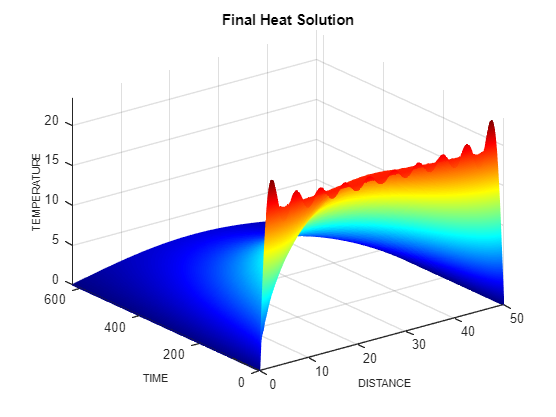

figure
colormap jet
tau = L^2/D;
fsurf(heatSolN,[0 L 0 tau/4],"EdgeColor","interp")
title("Final Heat Solution")
xlabel('DISTANCE','FontSize',8)
ylabel('TIME','FontSize',8)
zlabel('TEMPERATURE','FontSize',8)

**Heat profile at different times**

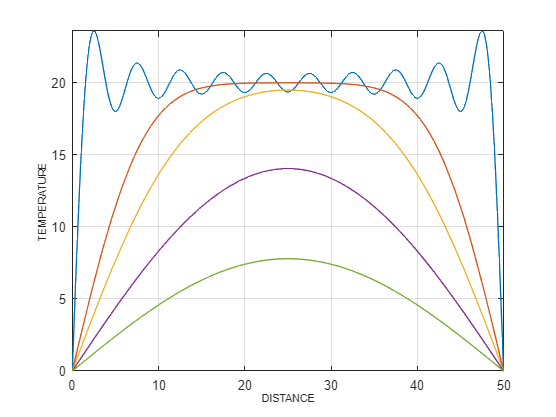

clf 
tm = [0 20 50 150 300];
for i = 1:length(tm)
    sn = matlabFunction(heatSolN(x,tm(i)));
    fplot(sn,[0 L])
    grid on, hold on
end
xlabel('DISTANCE','FontSize',8);
ylabel('TEMPERATURE','FontSize',8)

**Heat profile at various distances**

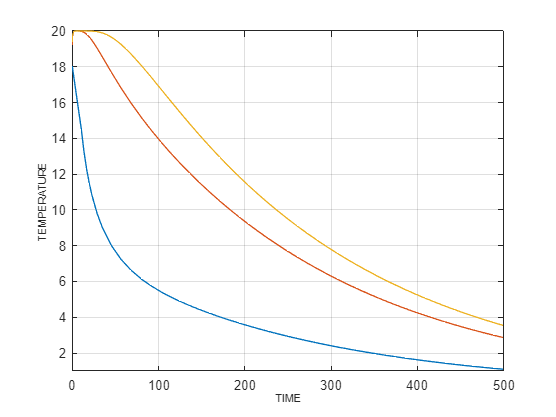

clf
dst = [5 15 25];
for i = 1:length(dst)
    sn = matlabFunction(heatSolN(dst(i),t));
    fplot(sn, [0 500])
    grid on , hold on
end
xlabel('TIME','FontSize',8);
ylabel('TEMPERATURE','FontSize',8)